# Solution to the *Activity Data: Import and Organize *exercise

## 1. Import data

Import the data in `ActivityData.txt `as a table.

data = readtable('ActivityData.txt');

This file contains  44 columns containing smartphone sensor information for experimental participants performing 6 different activities. The second column contains a string label for the activity being performed. The first row of the text file represents the labels for each column.

The data is available from the Machine Learning Repository at the University of California, Irvine: [https://archive.ics.uci.edu/ml/datasets/Human+Activity+Recognition+Using+Smartphones](https://archive.ics.uci.edu/ml/datasets/Human+Activity+Recognition+Using+Smartphones)

## 2. Convert activity to categorical

Convert the `Activity` variable to a categorical data type.

data.Activity = categorical(data.Activity);

## 3. Use grpstats to find mean and std by activity

Determine the mean and standard deviation of the variable `GravAccMeanZ `for each activity.

[m,s] = grpstats(data.GravAccMeanZ,data.Activity,{@mean,@std})

m =    -0.0529
    0.5062
    0.1179
   -0.0372
   -0.1451
   -0.0598


s =     0.1541
    0.4439
    0.1904
    0.1427
    0.1967
    0.1484



cats = categories(data.Activity)

cats = 6×1 cell array
    {'DownStairs'}
    {'Laying'    }
    {'Sitting'   }
    {'Standing'  }
    {'UpStairs'  }
    {'Walking'   }


## 4. Visualize by group

Create a grouped scatter plot with `AccEnergyZ` on the *x*-axis and `GravAccEnergyZ` on the *y*-axis, grouped by `Activity`.

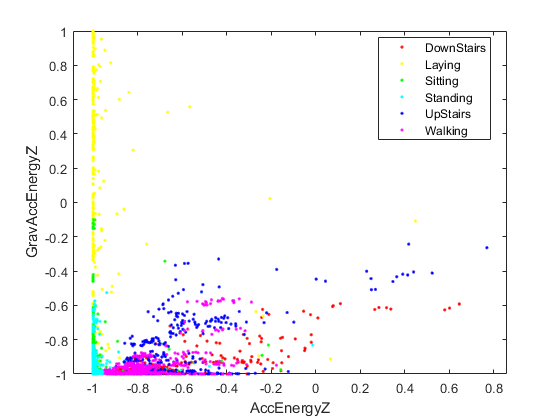

figure
gscatter(data.AccEnergyZ,data.GravAccEnergyZ,data.Activity)
xlabel('AccEnergyZ')
ylabel('GravAccEnergyZ')